## Model and parameters

The Holling Type II model is used for local reactions, using the same parameters as in previous implementations. Relatively low diffusion coefficients are used in order to ensure numerical stability, and to retain some local variance, as too quick diffusion will smooth out results.

a = 0.5;  % Prey grows by 50% monthly in absence of predators
b = 0.02; % Prey encounters per month per predator
c = 0.4;  % Predator efficiency (in converting prey into offspring)
d = 0.4;  % Predator population declines by 40% monthly in absence of prey
K = 100;  % Carrying capacity
h = 0.2;  % 6 days to chase, hunt and eat prey

f = @(t,P,Z) a*P.*(1-P/K)-b*P.*Z./(1+b*h*P);
g = @(t,P,Z) c*b*P.*Z./(1+b*h*P) - d*Z;

prey = 40; predator = 20; Nx = 100; Ny = 100;
P0 = prey * (1 + 0.5*rand(Nx,Ny));
Z0 = predator * (1 + 0.5*rand(Nx,Ny));
Dp = 1e-5; Dz = 1e-5;
n = 1000; t_end = 24;

[dt_min, n_min] = CFL(Dp,Dz,Nx,Ny,t_end)

dt_min = 2.5508

n_min = 10

## Simulation using Explicit Euler

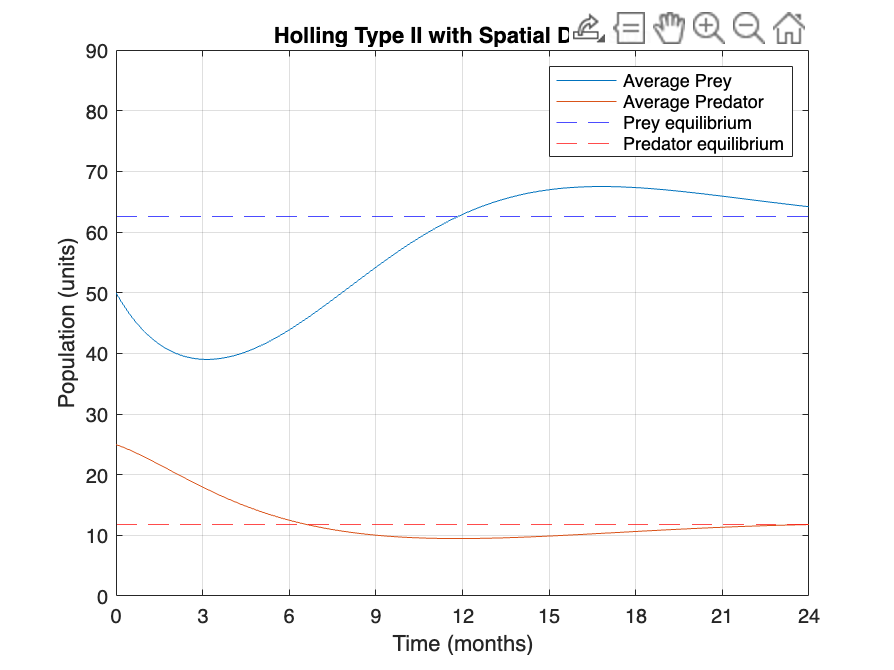

[t,P,Z] = EulerDiffusion(f,g, P0, Z0, Dp, Dz, t_end, n);

% Average population plot
figure()
plot(t,squeeze(mean(P, [1 2])))
hold on
plot(t,squeeze(mean(Z, [1 2])))
hold off
grid

pred_eq = -a*c*(d-b*c*K+b*d*h*K)/(b^2*(c-d*h)^2*K);
prey_eq = d/(b*(c-h*d));

yline(prey_eq, "--",Color="b");
yline(pred_eq, "--",Color="r");
legend("Average Prey","Average Predator","Prey equilibrium","Predator equilibrium",location="northeast")
title("Holling Type II with Spatial Diffusion")

xlim([0 t_end])
ylim([0 90])
xticks(0:3:t_end)
ylabel("Population (units)")
xlabel("Time (months)")

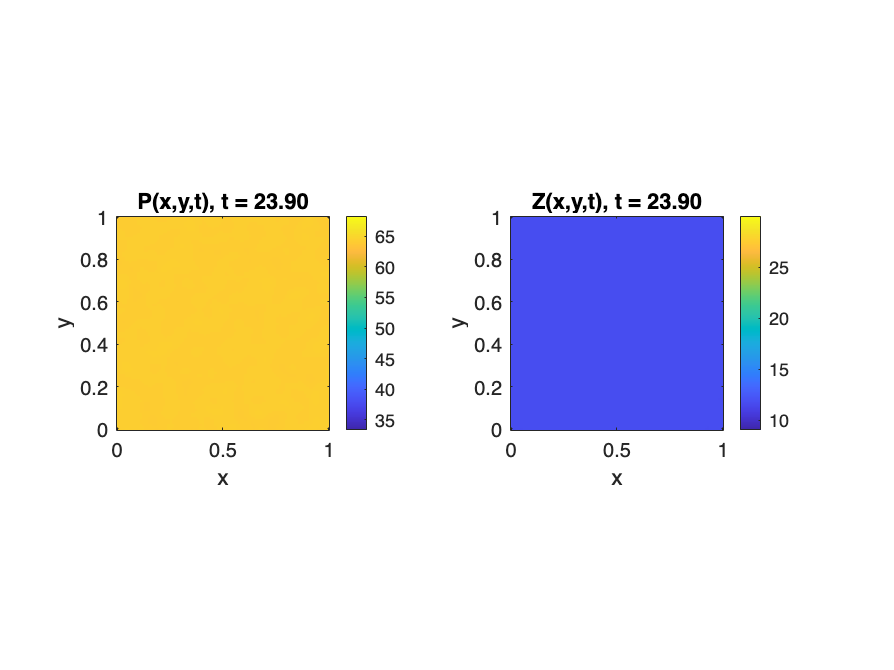


DiffusionPlot(t,P,Z)

It can be seen how the spatial average over time has a very similar behavior compared to the regular Holling simulation. In order to provide some spatial dynamic, instead of setting a constant initial conditon, a randomly perturbated map aroudn teh initial condition is used. However, due to the method being stable, coupled with diffusion, the population map ends up converging to the stable value all over the spatial domain.

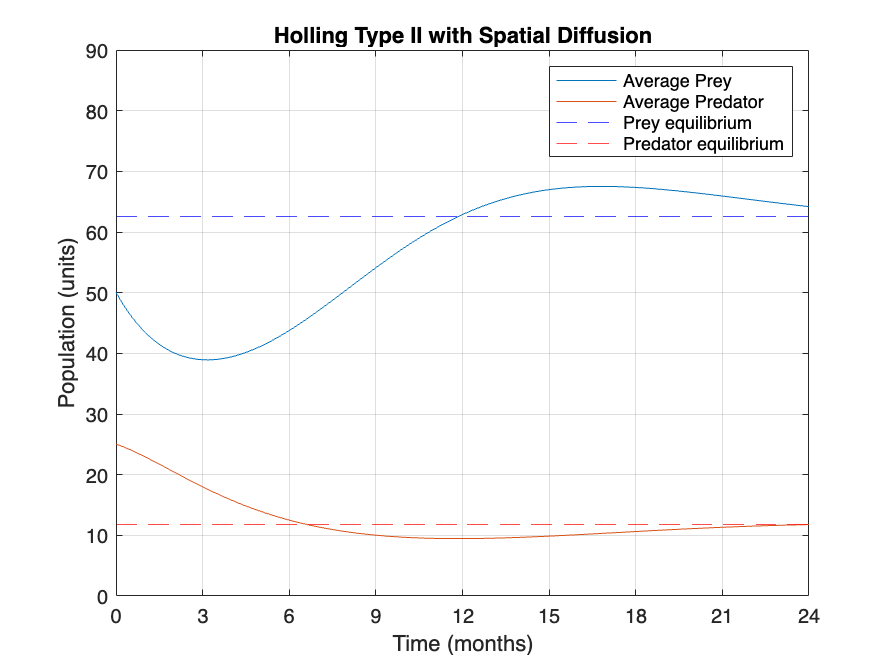

[t,P,Z] = EulerDiffusionSparce(f,g, P0, Z0, Dp, Dz, t_end, n);

% Average population plot
figure()
plot(t,squeeze(mean(P, [1 2])))
hold on
plot(t,squeeze(mean(Z, [1 2])))
hold off
grid

pred_eq = -a*c*(d-b*c*K+b*d*h*K)/(b^2*(c-d*h)^2*K);
prey_eq = d/(b*(c-h*d));

yline(prey_eq, "--",Color="b");
yline(pred_eq, "--",Color="r");
legend("Average Prey","Average Predator","Prey equilibrium","Predator equilibrium",location="northeast")
title("Holling Type II with Spatial Diffusion")

xlim([0 t_end])
ylim([0 90])
xticks(0:3:t_end)
ylabel("Population (units)")
xlabel("Time (months)")


disp('Holling Type II spacetime representation (horizontal slices)')

Holling Type II spacetime representation (horizontal slices)


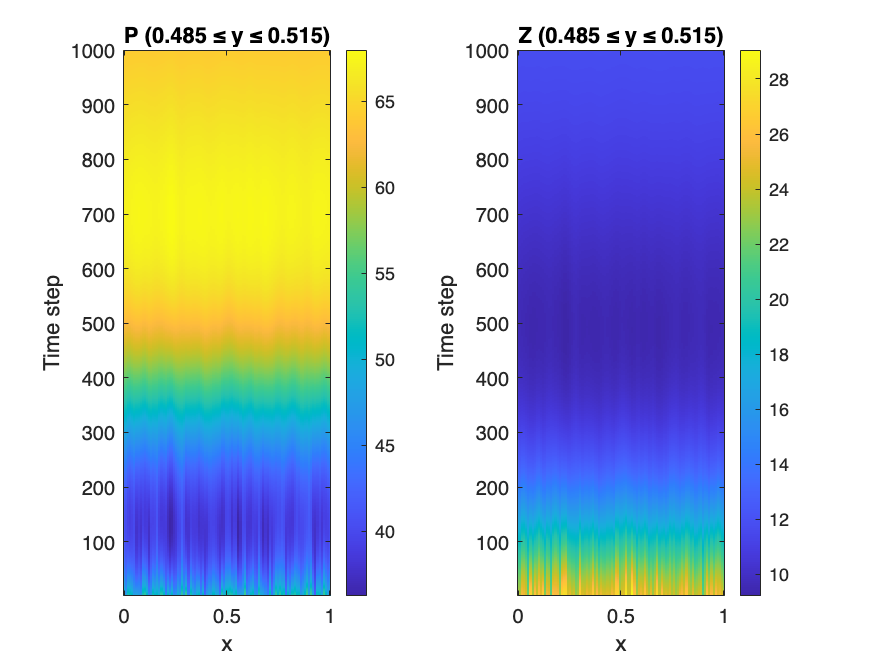

SpacetimeBand(P, Z, 0.5, 0.05)

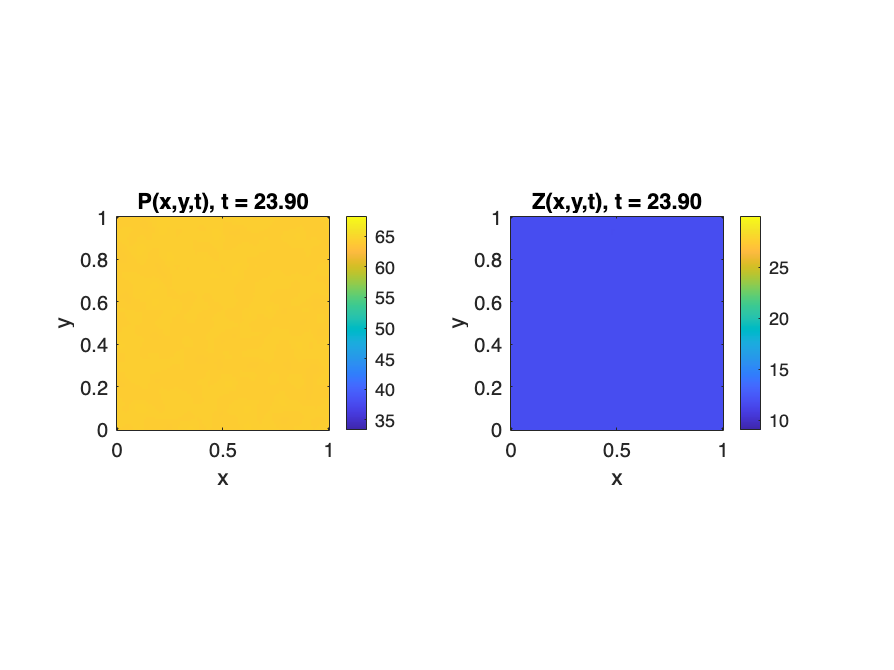


DiffusionPlot(t,P,Z)

In order to be able to statically observe the model behavior, a spacetime representation is used, showing the behavior of a certain horizontal slice over time

## Non-autonomous methods

Note how these solvers also work for any of the other previous methods, for example the non autonomous variation also shown in the SeasonalGrowth notebook.

A = 0.75;  % Prey grows by 50% monthly in absence of predators
b = 0.02; % Prey encounters per month per predator
c = 0.4;  % Predator efficiency (in converting prey into offspring)
d = 0.4;  % Predator population declines by 40% monthly in absence of prey
K = 100;  % Carrying capacity
h = 0.2;  % 6 days to chase, hunt and eat prey
alpha = 0.5;
phi = 3;

f = @(t,P,Z) A*(1/2+cos(pi*t/12).^2)*P.*(1-P/K)-b*P.*Z./(1+b*h*P);
g = @(t,P,Z) c*b*P.*Z./(1+b*h*P) - d*(1+alpha*cos(pi*(t+phi)/6))*Z;

prey = 40; predator = 20; Nx = 100; Ny = 100;
P0 = prey * (1 + 0.75*rand(Nx,Ny));
Z0 = predator * (1 + 0.75*rand(Nx,Ny));
Dp = 1e-5; Dz = 1e-5;
n = 1000; t_end = 48;

[dt_min, n_min] = CFL(Dp,Dz,Nx,Ny,t_end)

dt_min = 2.5508

n_min = 19

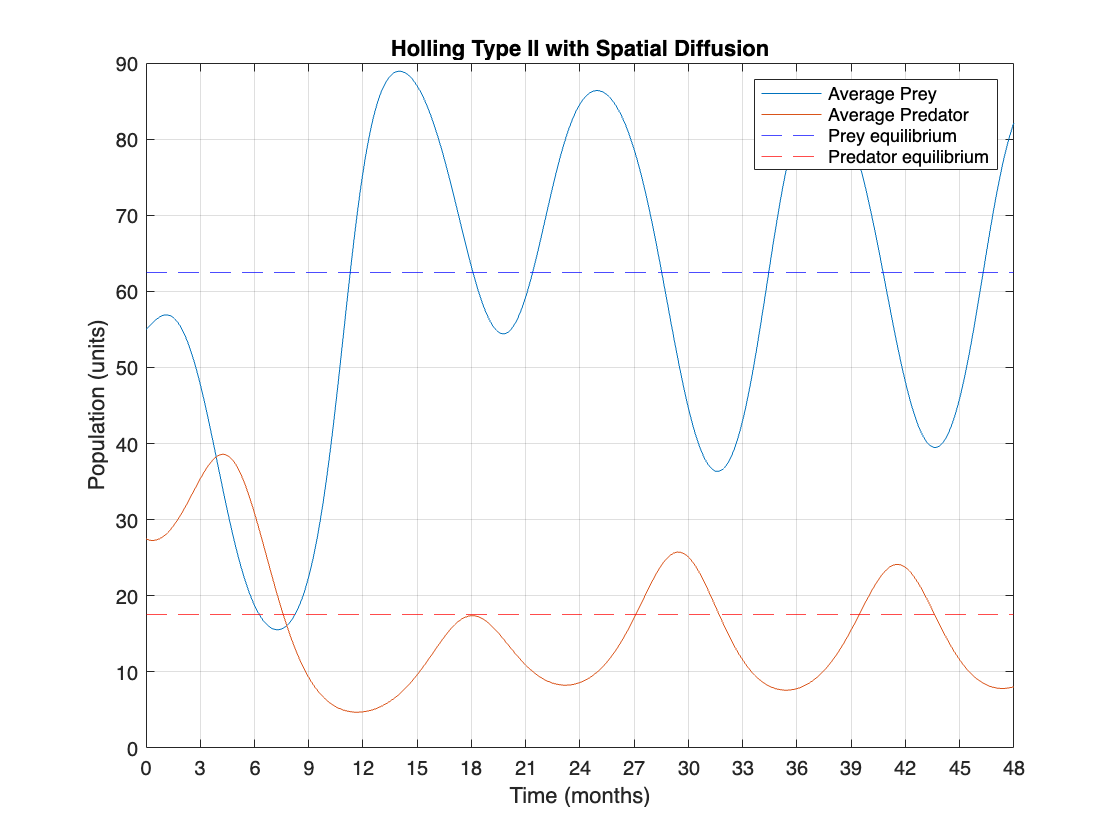

[t,P,Z] = EulerDiffusionSparce(f,g, P0, Z0, Dp, Dz, t_end, n);

% Average population plot
figure()
plot(t,squeeze(mean(P, [1 2])))
hold on
plot(t,squeeze(mean(Z, [1 2])))
hold off
grid

pred_eq = -A*c*(d-b*c*K+b*d*h*K)/(b^2*(c-d*h)^2*K);
prey_eq = d/(b*(c-h*d));

yline(prey_eq, "--",Color="b");
yline(pred_eq, "--",Color="r");
legend("Average Prey","Average Predator","Prey equilibrium","Predator equilibrium",location="northeast")
title("Non Autonomous model with Spatial Diffusion")

xlim([0 t_end])
ylim([0 90])
xticks(0:3:t_end)
ylabel("Population (units)")
xlabel("Time (months)")


disp('Non Autonomous model spacetime representation (horizontal slices)')

Holling Type II spacetime representation (horizontal slices)


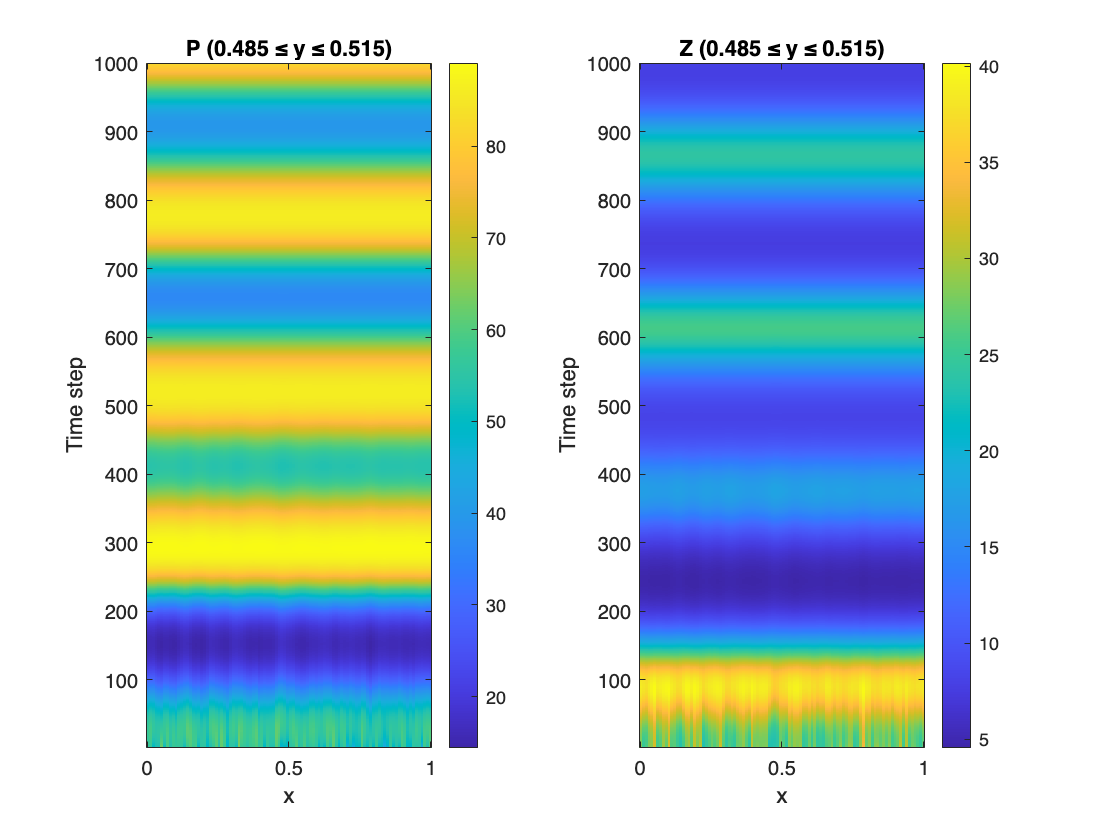

SpacetimeBand(P, Z, 0.5, 0.05)

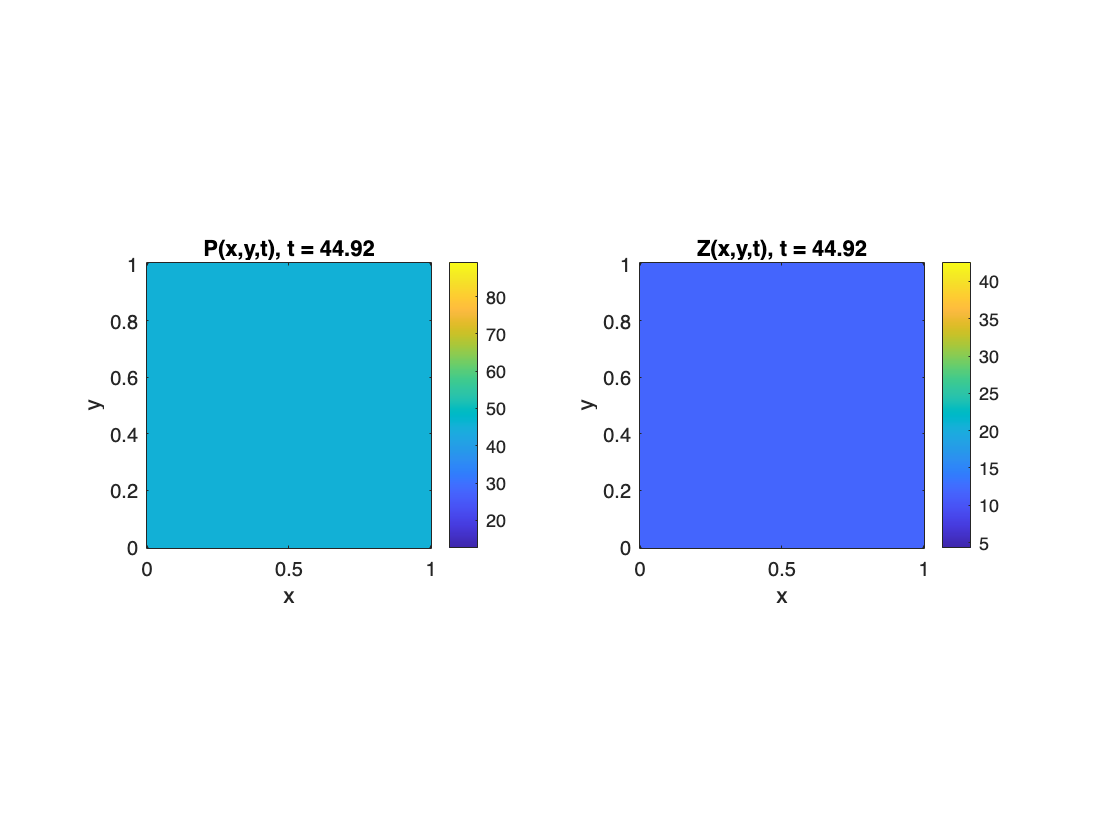


DiffusionPlot(t,P,Z)

## Initial conditions

The other posibility reaction-diffusion models offer is the variation of initial conditions. While random noise perturbations generally leads to patterns that stabilize over time, different initial configurations can lead to interesting dynamics.

A = 0.75;  % Prey grows by 50% monthly in absence of predators
b = 0.02; % Prey encounters per month per predator
c = 0.4;  % Predator efficiency (in converting prey into offspring)
d = 0.4;  % Predator population declines by 40% monthly in absence of prey
K = 100;  % Carrying capacity
h = 0.2;  % 6 days to chase, hunt and eat prey
alpha = 0.5;
phi = 3;

f = @(t,P,Z) A*(1/2+cos(pi*t/12).^2)*P.*(1-P/K)-b*P.*Z./(1+b*h*P);
g = @(t,P,Z) c*b*P.*Z./(1+b*h*P) - d*(1+alpha*cos(pi*(t+phi)/6))*Z;

prey = 40; predator = 20; Nx = 100; Ny = 100;
Dp = 1e-5; Dz = 1e-5;
n = 1000; t_end = 24;

x = linspace(0,1,Nx);
y = linspace(0,1,Ny);
[X,Y] = meshgrid(y,x);
A = 0.8;
sigma = 0.08;

P0 = prey*ones(Nx,Ny);
Z0 = predator + A*predator*exp(-((X-0.5).^2 + (Y-0.5).^2)/(2*sigma^2));

[dt_min, n_min] = CFL(Dp,Dz,Nx,Ny,t_end)

dt_min = 2.5508

n_min = 10

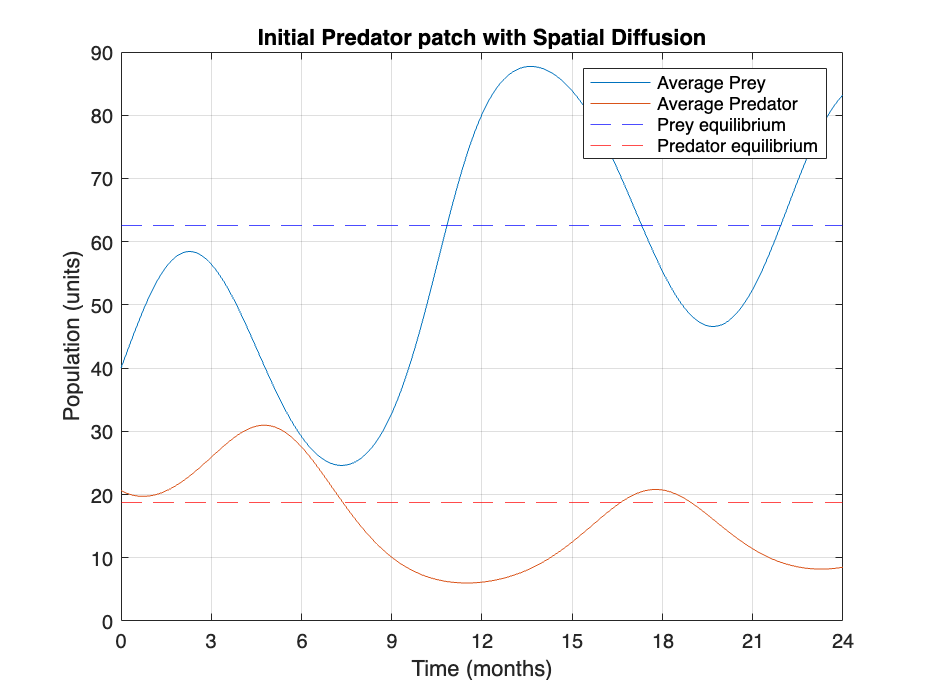

[t,P,Z] = EulerDiffusionSparce(f,g, P0, Z0, Dp, Dz, t_end, n);

% Average population plot
figure()
plot(t,squeeze(mean(P, [1 2])))
hold on
plot(t,squeeze(mean(Z, [1 2])))
hold off
grid

pred_eq = -A*c*(d-b*c*K+b*d*h*K)/(b^2*(c-d*h)^2*K);
prey_eq = d/(b*(c-h*d));

yline(prey_eq, "--",Color="b");
yline(pred_eq, "--",Color="r");
legend("Average Prey","Average Predator","Prey equilibrium","Predator equilibrium",location="northeast")
title("Initial Predator patch with Spatial Diffusion")

xlim([0 t_end])
ylim([0 90])
xticks(0:3:t_end)
ylabel("Population (units)")
xlabel("Time (months)")


disp('Initial Predator patch spacetime representation (horizontal slices)')

Initial Predator patch spacetime representation (horizontal slices)


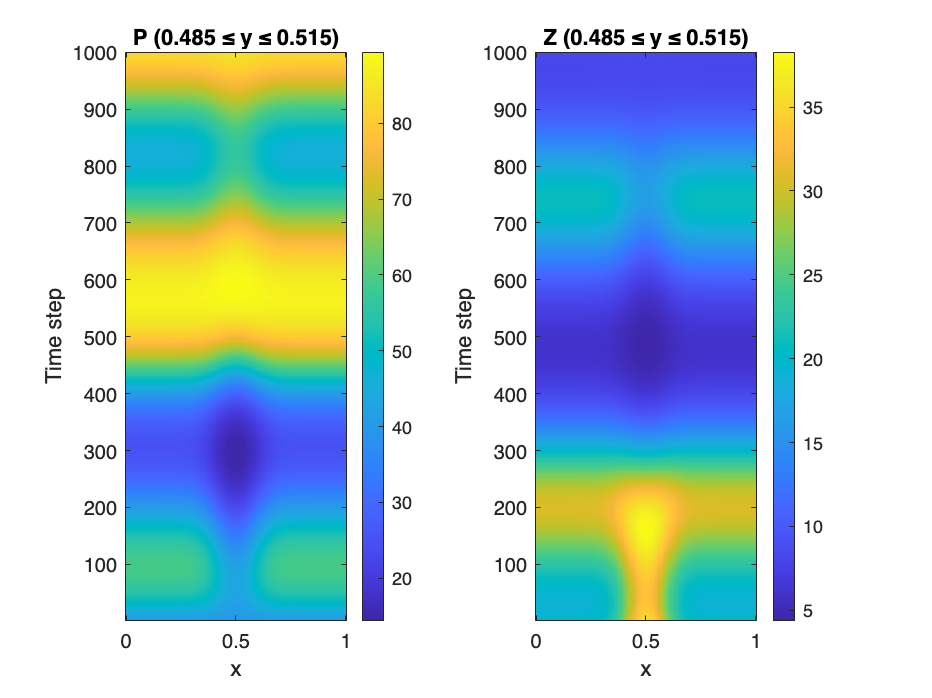

SpacetimeBand(P, Z, 0.5, 0.05)

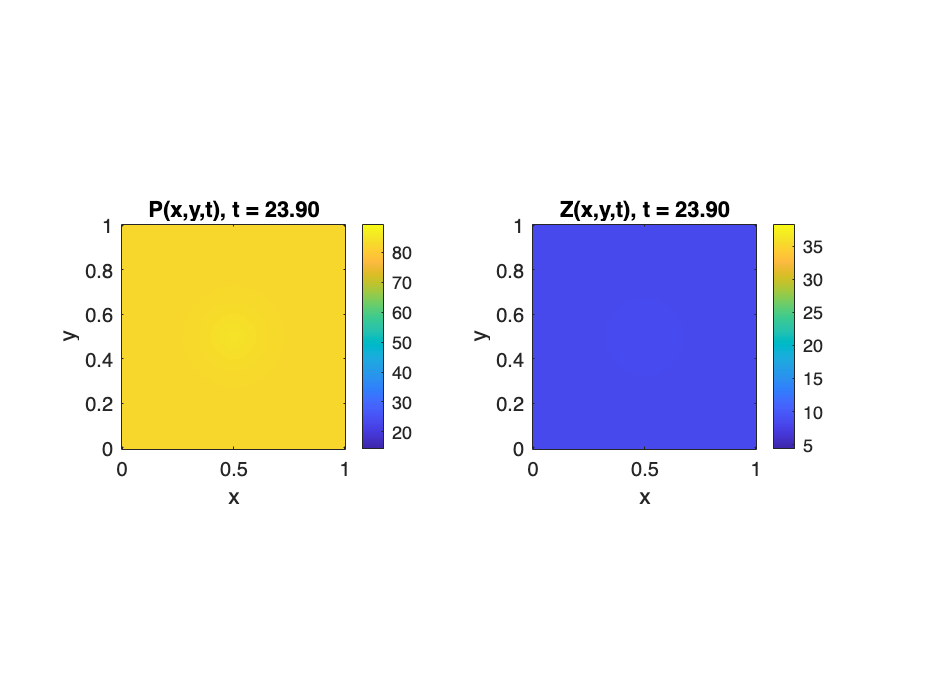


DiffusionPlot(t,P,Z)

When a predator patch in the center is used as an initial condition, it will lead to local extintion of prey, as well as predator diffusion, which will eventually dilute into the whole grid.

## Prey ring with noise

a = 0.75;  % Prey grows by 50% monthly in absence of predators
b = 0.05;  % Prey encounters per month per predator
c = 0.25;  % Predator efficiency (in converting prey into offspring)
d = 0.4;   % Predator population declines by 40% monthly in absence of prey
K = 100;   % Carrying capacity
h = 0.2;   % 6 days to chase, hunt and eat prey

f = @(t,P,Z) a*P.*(1-P/K)-b*P.*Z./(1+b*h*P);
g = @(t,P,Z) c*b*P.*Z./(1+b*h*P) - d*Z;

prey = 40; predator = 20; Nx = 100; Ny = 100;
Dp = 1e-5; Dz = 5e-5;
n = 1000; t_end = 24;

A = 0.8;
r = sqrt((X-0.5).^2 + (Y-0.5).^2);
r0 = 0.2;
sigma = 0.03;
P0 = prey + A*prey*exp(-(r-r0).^2/(2*sigma^2));
Z0 = predator * (1 + 0.25*rand(Nx,Ny));
[dt_min, n_min] = CFL(Dp,Dz,Nx,Ny,t_end)

dt_min = 0.5102

n_min = 48

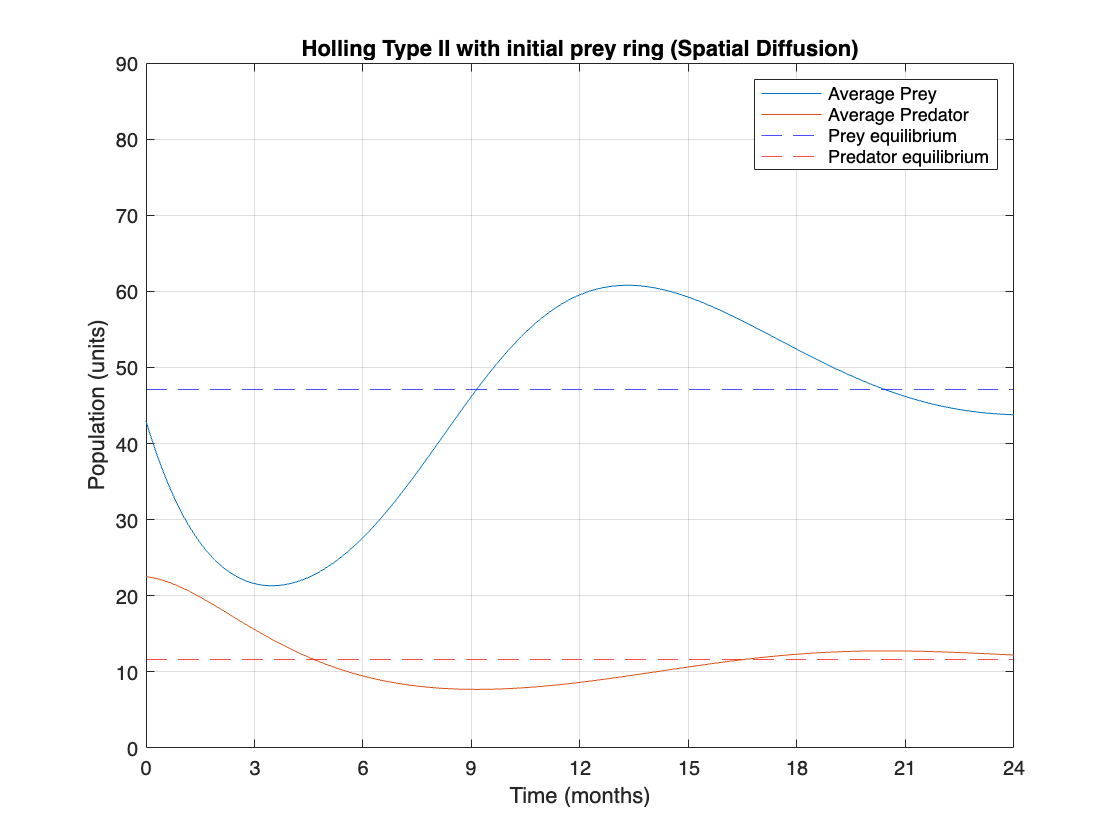

[t,P,Z] = EulerDiffusionSparce(f,g, P0, Z0, Dp, Dz, t_end, n);

% Average population plot
figure()
plot(t,squeeze(mean(P, [1 2])))
hold on
plot(t,squeeze(mean(Z, [1 2])))
hold off
grid

pred_eq = -a*c*(d-b*c*K+b*d*h*K)/(b^2*(c-d*h)^2*K);
prey_eq = d/(b*(c-h*d));

yline(prey_eq, "--",Color="b");
yline(pred_eq, "--",Color="r");
legend("Average Prey","Average Predator","Prey equilibrium","Predator equilibrium",location="northeast")
title("Holling Type II with initial prey ring (Spatial Diffusion)")

xlim([0 t_end])
ylim([0 90])
xticks(0:3:t_end)
ylabel("Population (units)")
xlabel("Time (months)")


disp('Holling Type II with initial prey ring spacetime representation (horizontal slices)')

Holling Type II with initial prey ring spacetime representation (horizontal slices)


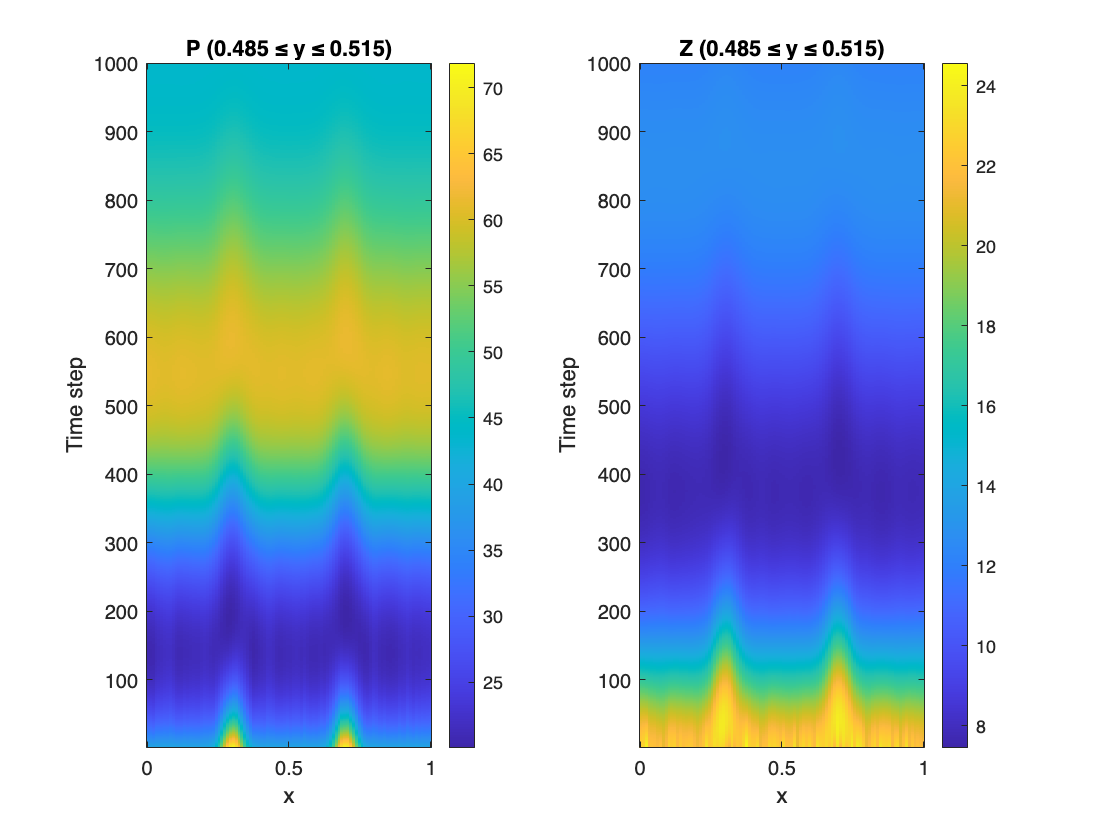

SpacetimeBand(P, Z, 0.5, 0.05)

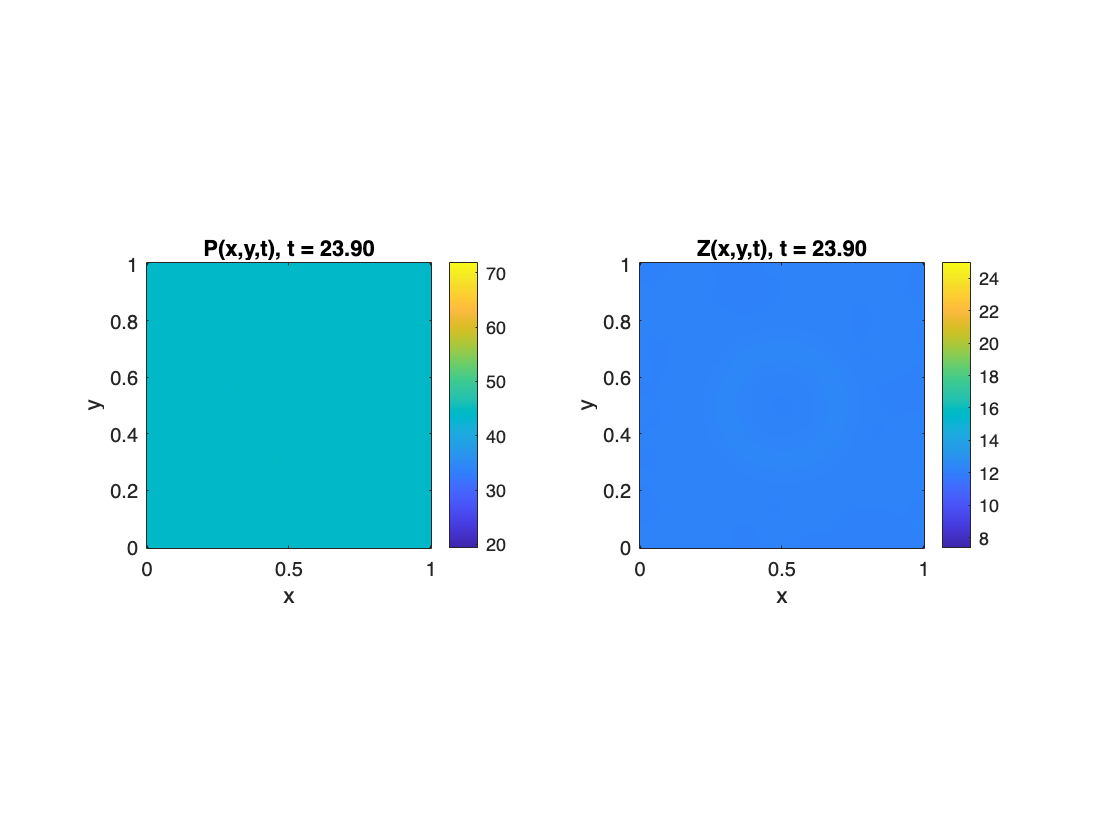


DiffusionPlot(t,P,Z)